## Walk-through: cross-frequency coupling

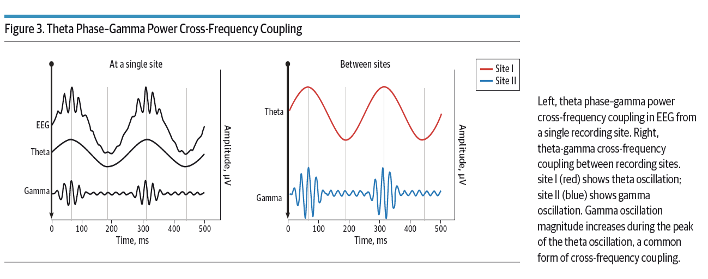

% first load example data, make sure the data are in the current directory,
% or in the path
clear
cd /Users/andreaskeil/Desktop/tempdata/Dom_alpha_testOct2025
load('OCA_3139.trls.1.mat') % loads our example data set (257 sensors, 31000 points, 2 trials)
size(Mat3D)

ans =          257       31000           2


SampRate = 500; 
data = reshape(Mat3D, [257, 1000, 62]);


As a reminder, this data set is from a simple task:

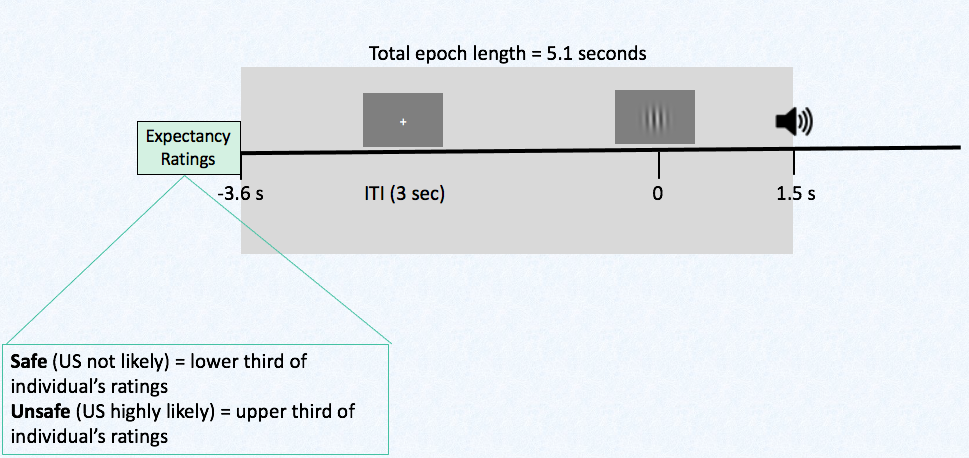

Now we set the parameters for a wavelet transform, we may as well use the Hilbert Transform. If you are not sure when to use which method, now is a good time to ask...

  1. Read data to get info and set the parameters you want

  % Settings
  NPointsNew = size(data,2);   
  NTrials = size(data,3);   
  allfreqspossible = 0:1000./(NPointsNew.*1000/SampRate):SampRate/2; % a vector (a list) of the frequencies
  
  % do an FFT on the data and look at spectrum at three midline channels
  [specavg, freqs] = FFT_spectrum3D(data, 1:1000, 500); 
  subplot(3,1,1), plot(freqs(2:80), specavg(6,2:80))

  % User sets these parameters
  fdelta = 4; % take only every 4th frequency of the ones that you could compute
  f0start = 20; 
  f0end = 200; 
  
  f0phase = 4; 
  f0power = 35; 
  
  timeinterval = 300:1800; % the time you want to analyze CFC within each trial in sample points. 
  % Important: wavelets are calculated for the full matrix, not just for this  interval 

 2. Compute wavelets and their parameters 

  wavelet = gener_wav(NPointsNew, fdelta, f0start, f0end);
 
  disp('size of waveletMatrix')
  disp(size(wavelet))
  disp (' frequency step for delta_f0 = 1 is ')
  disp(SampRate/NPointsNew)
  disp(' actual wavelet frequencies (Hz) selected with these settings: ')
  disp(allfreqspossible(f0start:fdelta:f0end))
  reducedfreqs = allfreqspossible(f0start:fdelta:f0end); % the subset of frequencies that we actually use
  disp(' wavelet frequencies (Hz) used for CFC: ')
  disp(reducedfreqs([f0phase, f0power]))
  

3. Now, go through the trials, compute phase (lower frewquency) and power (higher frequency) 

  waveletMat3d = repmat(wavelet, [1 1 size(data,1)]); 
  waveletMat3d = permute(waveletMat3d, [3, 2, 1]); 
    
    % loop over trials    
    disp(['trial index of '])
    disp(NTrials)    
    warning('off')
    
    CFC = zeros(size(data,1),1);
    
    for trialindex = 1:NTrials          
        Data = data(:,:,trialindex);        
        fprintf('.')
         
        if trialindex/10 == round(trialindex/10), disp(trialindex), end    
        Data = bslcorr(Data, 1:100); 
        size(Data);

        % window data with cosine square window
        window = cosinwin(20, size(Data,2), size(Data,1)); 
        Data = Data .* window;         
        data_pad3d = repmat(Data, [1 1 size(wavelet,1)]); 
    
        % transform data  to the frequency domain
        data_trans = fft(data_pad3d, NPointsNew, 2);
        thetaMATLABretrans = []; 
        ProdMat= waveletMat3d .*(data_trans);
        thetaMATLABretrans = ifft(ProdMat, NPointsNew, 2);
        
        % standardize instantaneous phase, calculate phase and power for
        % each trial
        stdcomplexphasemat = thetaMATLABretrans ./ abs(thetaMATLABretrans);     
        powermat_all = abs(thetaMATLABretrans).* 10; 
        phasemat_all= angle(stdcomplexphasemat);
        
        % save the results in the matrices for phase and power, keep full
        % spectrum for sanity checks                      
        if trialindex == 1
           powermat = powermat_all(:, timeinterval, f0power);
           phasemat = phasemat_all(:, timeinterval, f0phase);
           fullspecmat = powermat_all;                 
        else
           powermat = [powermat powermat_all(:, timeinterval, f0power)];
           phasemat = [phasemat phasemat_all(:, timeinterval, f0phase)];
           fullspecmat = fullspecmat+powermat_all; 
        end

    end % loop over trials

    fullspecmat = fullspecmat./NTrials;
    spec = (squeeze(mean(fullspecmat, 2))')'; 
    figure, plot(reducedfreqs, spec'), title ('wavelet spectrum, all channels all trials'), xlabel ('frequency (Hz)'), ylabel ('integral power)')  

Now, create some example phase-amplitude historgrams

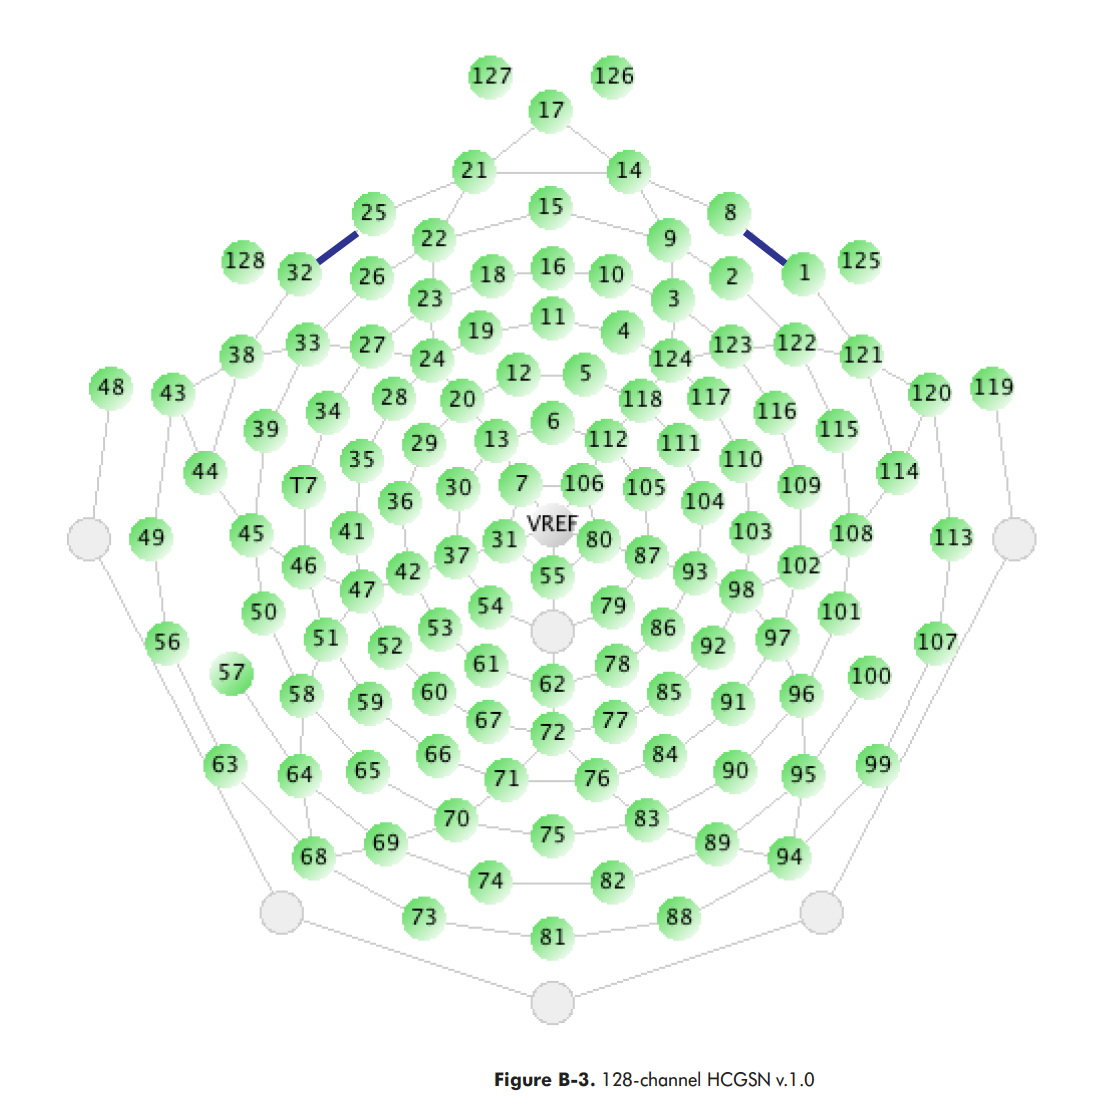

    %  create the phase-am histograms
   for chan = 1:size(data,1)
       
       if chan./10 == round(chan./10), disp(chan), end 
     
        [bins, centers] = hist(phasemat(chan,:), 21); 

        for x = 2:21
        indexvec = find(phasemat(chan, :) < centers(x) & phasemat(chan, :) > centers(x-1));
        powerbin(x-1)=mean(powermat(chan,indexvec));
        end

        powerbin_norm = powerbin./sum(powerbin); 
       if chan == 11, subplot(1,3,1), bar(centers(1:20), powerbin_norm), title(chan)
       elseif chan == 68, subplot(1,3,2), bar(centers(1:20), powerbin_norm), title(chan)
       elseif chan == 75, subplot(1,3,3), bar(centers(1:20), powerbin_norm), title(chan)
       end

        CFC(chan) = (max(powerbin_norm) - min(powerbin_norm))./ max(powerbin_norm); 
        

   end % chan
   

edit phaseampcoupling3d
% now try using the function and chaneg the settings :-) 